Sam Kramer

October 17th, 2023

## KCC Exploration

This live script is for the development of the Kernel Based Cross Correlator function kxcorr() that is going to be used in my research and thesis. This code is going to be in the CPU space and not in the GPU CUDA space that is used within the research. This mainly is going to explore the properties of the function itself and is more of a practical exercise.

%{
    KCC Exploration Notebook

    This live script is for the development of the Kernel Based Cross Correlator 
    function kxcorr() that is going to be used in my research and thesis. This code 
    is going to be in the CPU space and not in the GPU CUDA space that is used within 
    the research. This mainly is going to explore the properties of the function itself 
    and is more of a practical exercise.
   
    Sam Kramer
    October 17th, 2023
%}

% --Setup
    clear; clc; format compact; close all;

% --Signal Parameters
    T = 1;              % Signal Period T (s)
    fs = 10000;         % Sample Rate (Hz)
    t = 0:1/fs:T;
    f = 10*2*pi;        % Frequency (Hz)


## Noisy Signal with SNR = 5

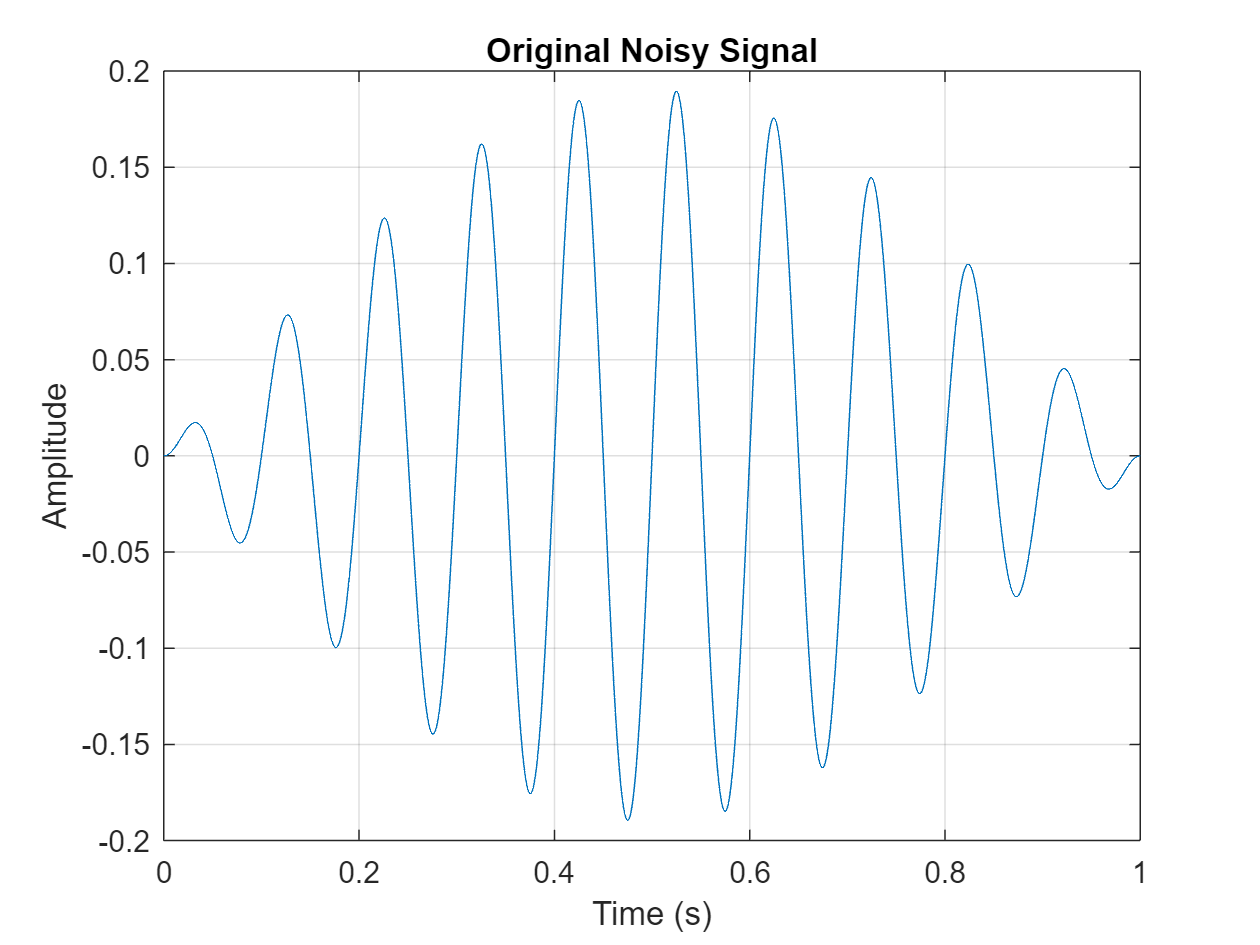

% --Create Signal
    amplitude = .19;
    envelope = amplitude.* sin(pi*t);
    signal = envelope .* sin(f*t);
    noisy_signal = randi(100,1,length(t))./400 + signal;
    noisy_signal = noisy_signal - mean(noisy_signal);

% --Show original signal
    figure(1)
    plot(t, signal)
        xlabel('Time (s)')
        ylabel('Amplitude')
        grid on
        hold on
        title('Original Noisy Signal')

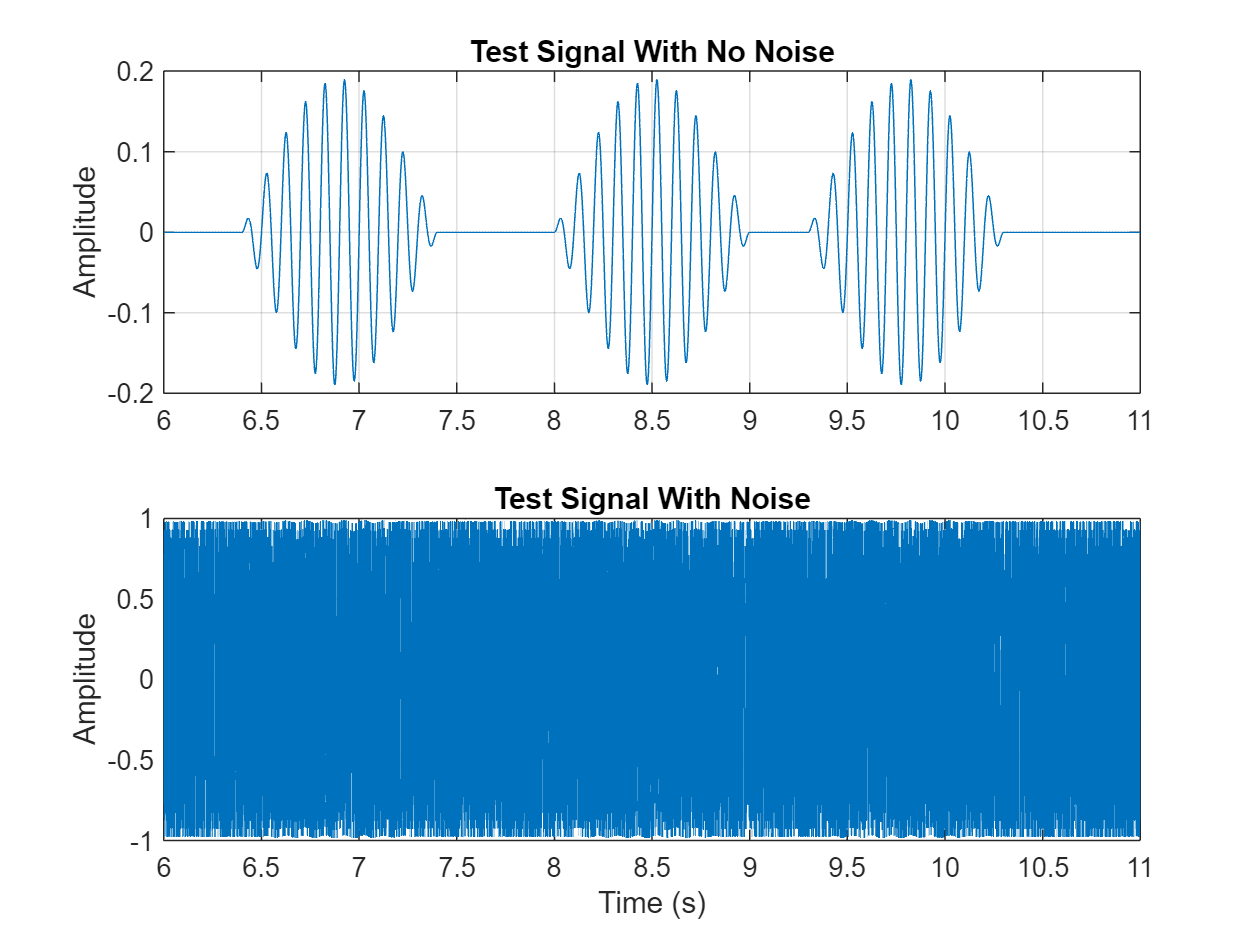


% --Creating a 10 second long noisy signal
    test_trial = zeros([1, fs*10 + 1]);
    num = [4.4; 6.3; 1; 2.2; 8];
    for i = 1:length(num)
        % --Place the signal into the test trial
            test_trial = [test_trial(1, 1:num(i)*fs) signal test_trial(1, num(i)*fs:end)];
    end

% --Add noise and create a time vector
    noise_amp = 40;
    time = 0:1/fs:(length(test_trial) - 1)/fs;
    noisy_trial = (randi(noise_amp,1,length(test_trial)) + test_trial)/(noise_amp/2);
    noisy_trial = noisy_trial - mean(noisy_trial);

% --Display entire signal
    figure()
    subplot(2,1,1)
    plot(time, test_trial)
        hold on
        grid on
        title('Test Signal With No Noise')
        ylabel('Amplitude')
        xlim([6 11])

    subplot(2,1,2)
    plot(time, noisy_trial)
        grid on
        hold on
        title('Test Signal With Noise')
        ylabel('Amplitude')
        xlabel('Time (s)')
        xlim([6 11])


% --Calculating SNR
    SNR = snr(noisy_signal, fs)

SNR = 5.2126



% --Correlation Work



## Noisy Signal with SNR = 0

% --Define New Signal (Change Amplitude and Time)




## Exploring different sub functions of our correlator

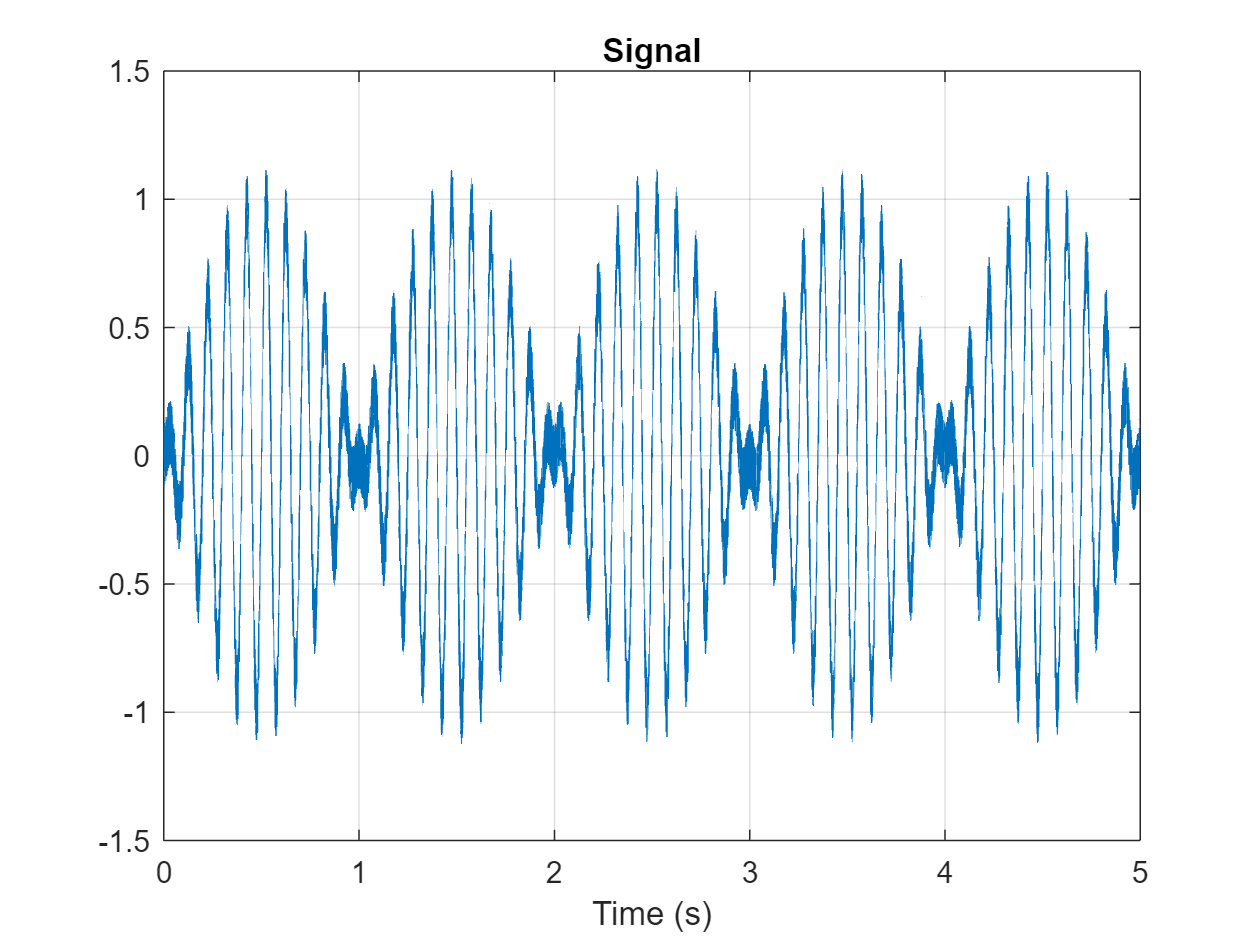

% --Create signal
    t = 0:1/fs:5;
    amplitude = 1;
    envelope = amplitude.* sin(pi*t);
    signal = envelope .* sin(f*t);
    noisy_signal = randi(100,1,length(t))./400 + signal;
    noisy_signal = noisy_signal - mean(noisy_signal);

% --Plot signal
    figure()
    plot(t,noisy_signal)
        grid on
        hold on
        xlabel('Time (s)')
        title('Signal')

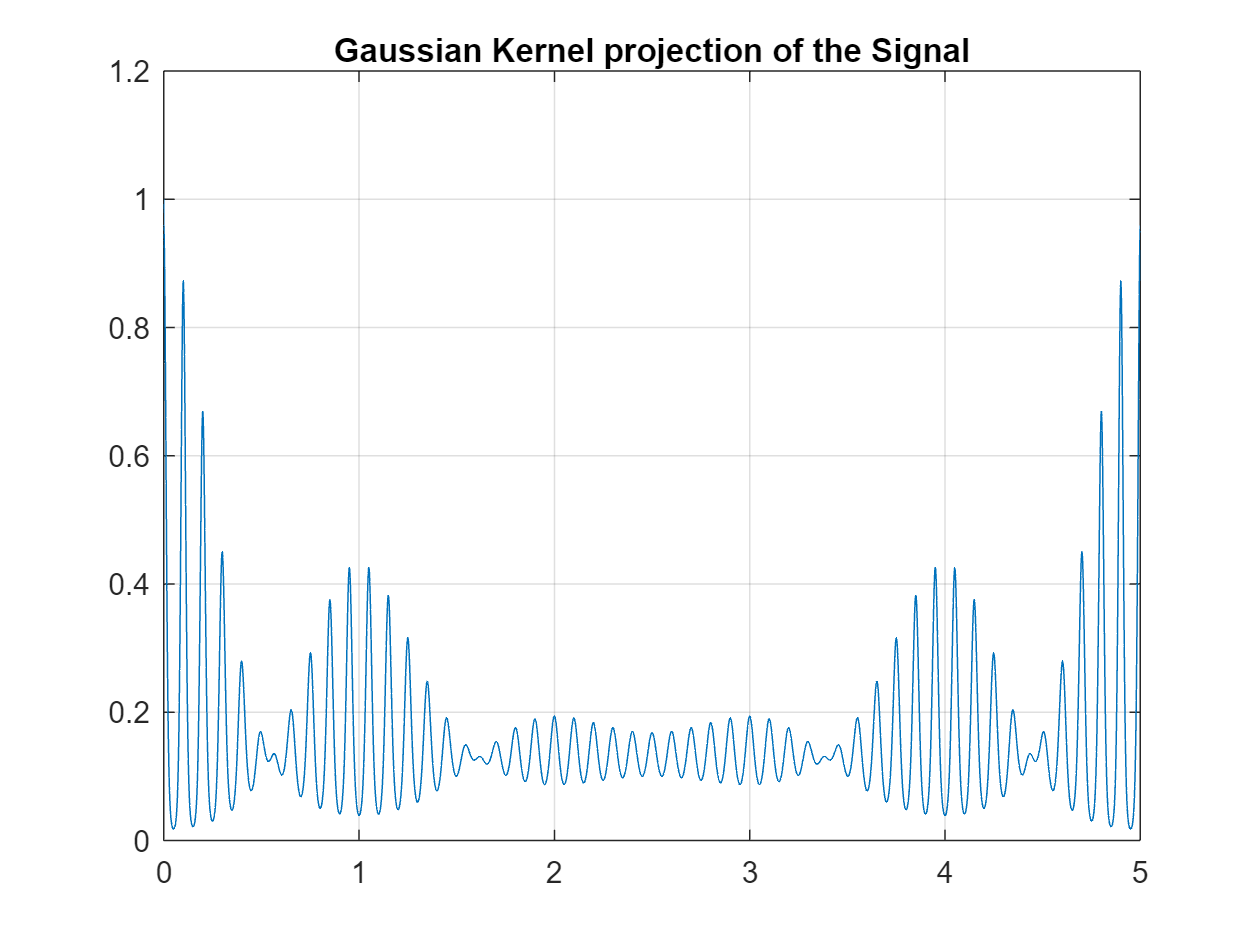


% --Calling gaussian_kernel
    f_sig = fft(noisy_signal);
    kf = gaussian_kernel(f_sig, f_sig, 0.5);

% --Plotting gaussian_kernel
    figure()
    plot(t, kf)
        hold on
        grid on
        title('Gaussian Kernel projection of the Signal')

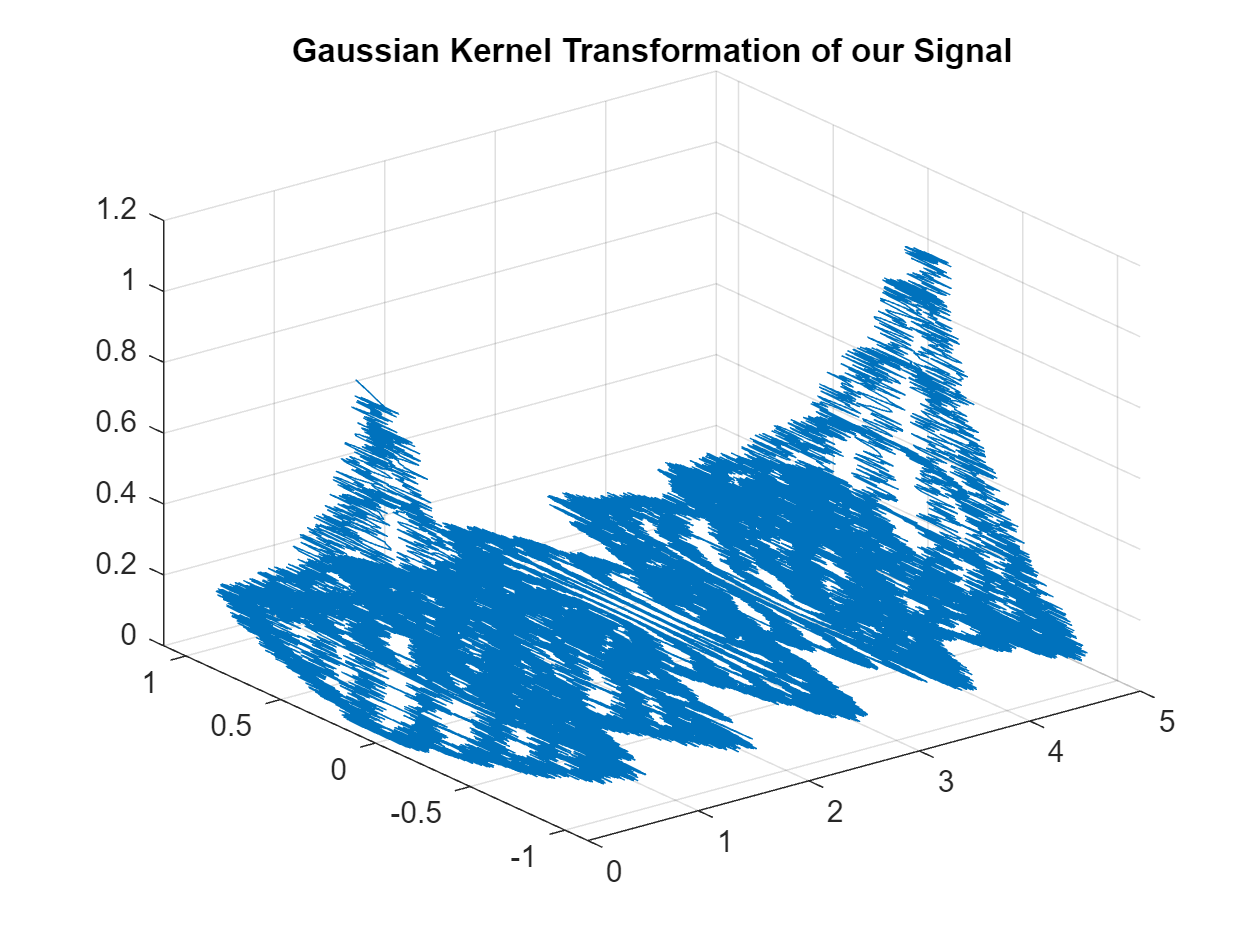


    figure()
    plot3(t,noisy_signal,kf)
        hold on
        grid on
        title('Gaussian Kernel Transformation of our Signal')

                Our Gaussian Kernel that we Just did actually made the smaller parts of our system larger, so we can linearly separate smaller parts of the signal from the larger amplitudes of the signal. The kernel decomposes the signal into dparts based on the amplitudes, so for our application, with weak signals, we can take the gaussian kernel of the signal to separate out the smaller parts of our signal that are perhaps hidden by the comparatively large noise. This also has applications beyond our dataset, becuase we can linearly separate out non-linear data that otherwise would not be linearly separable, this is the "kernel trick" in SVM and data science. 

    function output = kxcorr(test, sample)

        % --Parameters
            lambda = 0.001;
            sigma = 0.3;

        % --Setup
            test_fft = fft(test);

        % --Train Model
            correlator = train(sample, lambda, sigma);

        % --Compute output
            kernel_fft = fft(gaussian_kernel(test_fft, correlator.sample_fft, correlator.sigma));
            output = abs(ifft(correlator.correlator_fft.*kernel_fft));

    end

% --Define gaussian_kernel()
    function kf = gaussian_kernel(xf, yf, sigma)
    
        % --Setup Parameters
	        N = numel(xf);

        % --Perform Auto and Cross correlations
	        xx = xf(:)' * xf(:) / N;
	        yy = yf(:)' * yf(:) / N;
	        xy = ifft(xf .* conj(yf));
	    
        % --Find Kernel
            kf = exp(-1 / sigma^2 * (xx + yy - 2 * xy) / N);

    end

% --Define train()
    function correlator = train(sample, lambda, sigma)

        % --Early properties of the correlator
            correlator.sigma = sigma; 
            correlator.sample_fft = fft(sample);

        % --Calculating correlator 
            target_fft = ones(size(sample,1),1);
            kernel_fft = fft(gaussian_kernel(correlator.sample_fft, correlator.sample_fft, correlator.sigma));

            correlator.correlator_fft = target_fft./(kernel_fft + lambda);
    end